# 测试（间接法）

clc
clear
close all
addpath("src\");

## C-W交会

tf = 2000.; % s
x0 = [2200., 8000., 1000., 0., 0., 0.]';  % km, km/s
xf = zeros(6, 1);
p.n = 0.00111; % rad/s
p.tspan = 0.1; % s
p.f = 0.01; % N/kg; m/s^2

### 能量最优

@CostEnergy: $\int ||{\bf{u}}||^2 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    0.000000e+00    1.279e+04    2.842e-14
    1      14    9.817074e-02    1.544e+03    1.501e+04    1.113e-02
    2      21    8.484928e-02    1.737e-06    2.169e+04    2.326e-03


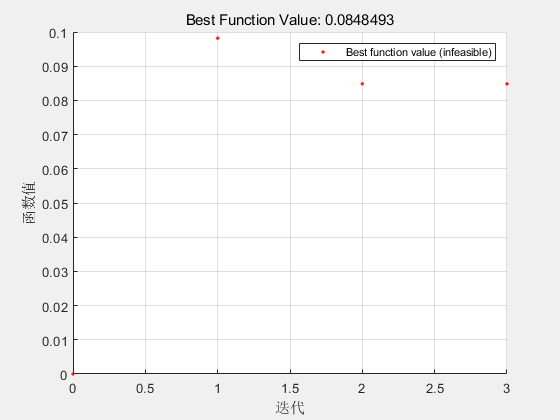


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[s,fval,exitflag,output] = IndirOptEnergy(@CwEnergyOpt, x0, xf, tf, p);

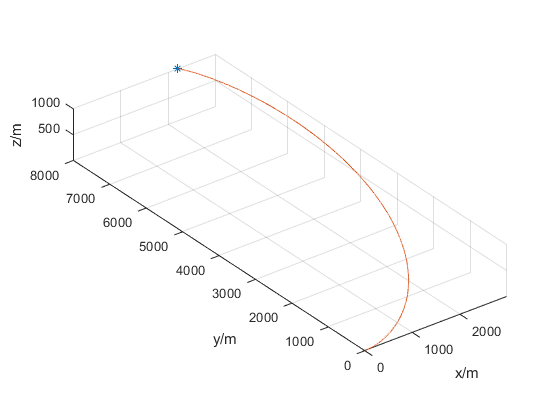

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

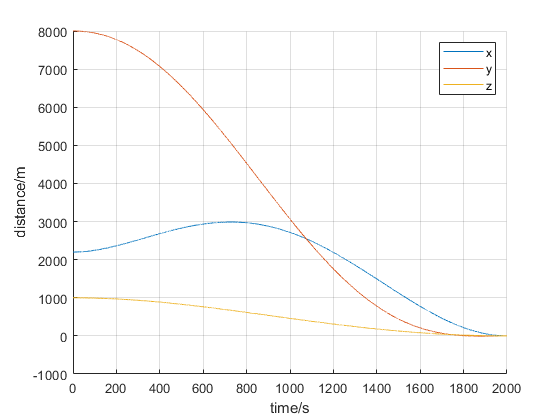

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

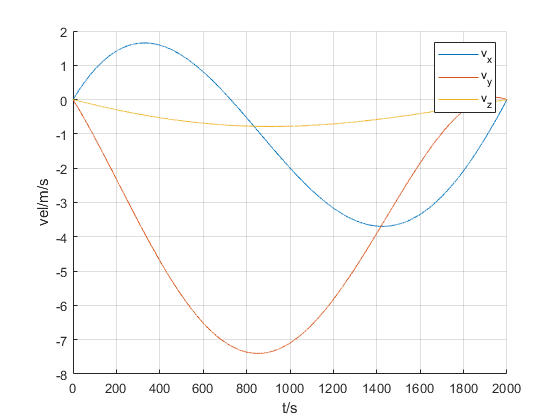

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

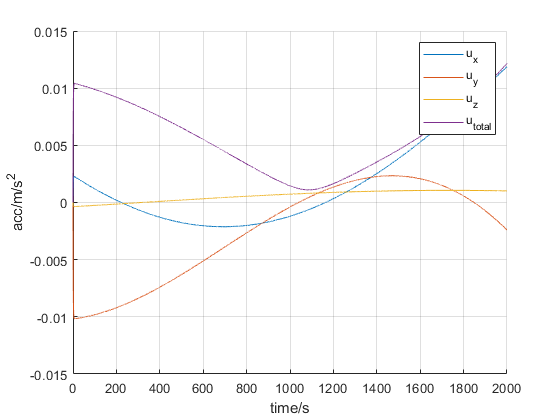

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 燃料最优（同伦）

@CostFuel: $\int \|{\bf{u}}\| \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       7    5.447791e-03    1.341e+04    1.665e-16
    1      14    8.194493e-02    4.629e+01    5.846e+04    2.091e+02
    2      21    8.498990e-02    6.369e+00    1.594e+03    4.138e+00
    3      28    8.513899e-02    7.599e-03    2.603e+01    2.299e-01
    4      35    8.513890e-02    1.957e-08    3.510e-03    1.272e-04
    5      42    8.513890e-02    4.621e-11    2.401e-08    1.637e-10

Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the <a h

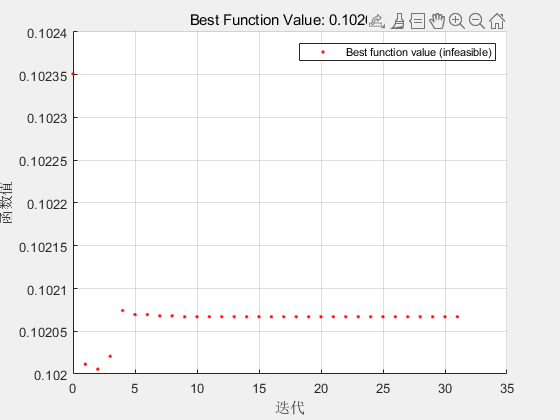


Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Consider enabling the interior point method feasibility mode.



[s,fval,exitflag,output] = IndirOptFuel(@CwFuelOpt, x0, xf, tf, p);

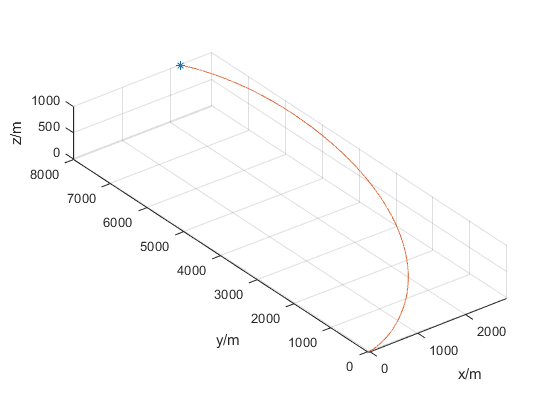

figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

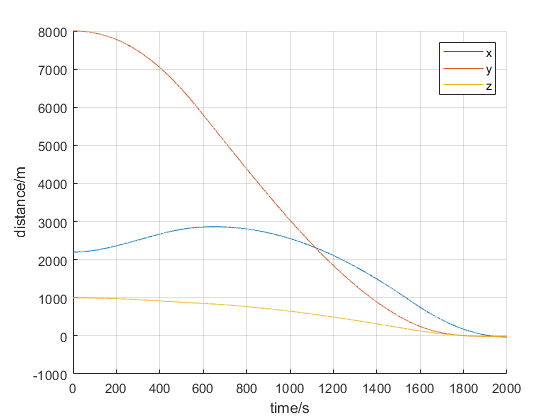

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

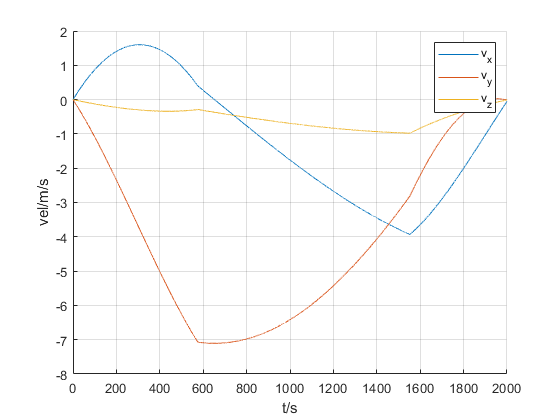

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

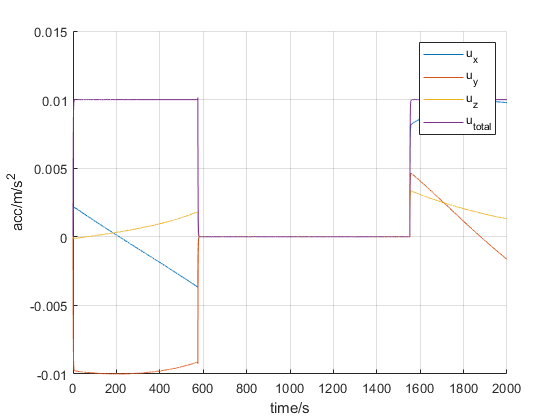

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off

### 时间最优

@CostEnergy: $\int 1 \mathrm{d}t$

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       8    1.800000e+03    2.388e+04    1.000e+00
    1      16    1.799000e+03    1.055e+04    9.999e-01    1.902e+00
    2      24    1.797090e+03    1.037e+04    9.999e-01    9.640e+01
    3      37    1.828486e+03    9.430e+03    9.999e-01    7.566e+01
    4      47    1.871150e+03    9.274e+03    9.999e-01    1.028e+02
    5      62    1.878455e+03    7.551e+03    9.999e-01    2.569e+01
    6      73    1.881501e+03    4.602e+03    1.024e+00    7.211e+00
    7      82    1.881268e+03    4.122e+02    2.122e+00    1.173e+00
    8      90    1.880814e+03    1.974e+01    1.001e+00    5.014e-01
    9      98    1.878507e+03    1.369e+01    1.001e+00    2.478e+00
   10     107    1.866976e+03    8.697e-01    1.001e+00    1.239e+01
   11     123    1.854937e+03    1.203e+00    1.000e+00    1.239e+01
   12     139    1.848743e+03    5.361e-01    1

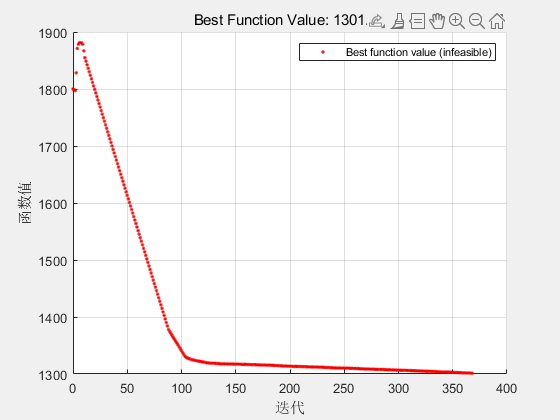


fmincon stopped by the output or plot function.



[s,fval,exitflag,output] = IndirOptTime(@(t, x) CwTimeOpt(t, x, p), x0, xf, tf, p);

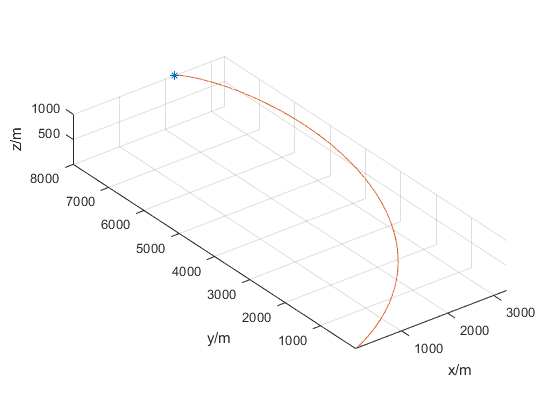

% [s,fval,exitflag,output] = IndirOptTime2(@CwTimeOpt3, x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime(@(t, x) CwEnergyOpt(t, x, p), x0, xf, tf, p);
% [s,fval,exitflag,output] = IndirOptTime3(@(t, x) CwTimeOpt2(t, x, p), x0, xf, tf, p);
figure
plot3(s(1, 2), s(1, 3), s(1, 4), '*')
hold on
plot3(s(:, 2), s(:, 3), s(:, 4))
grid on
axis equal
xlabel('x/m')
ylabel('y/m')
zlabel('z/m')
hold off

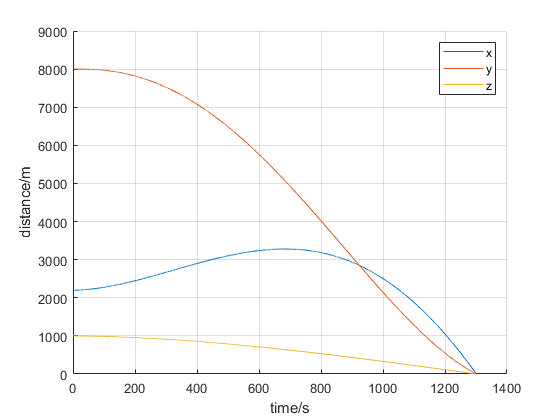

figure
hold on
plot(s(:, 1), s(:, 2 : 4))
grid on
legend('x', 'y', 'z')
xlabel('time/s')
ylabel('distance/m')
hold off

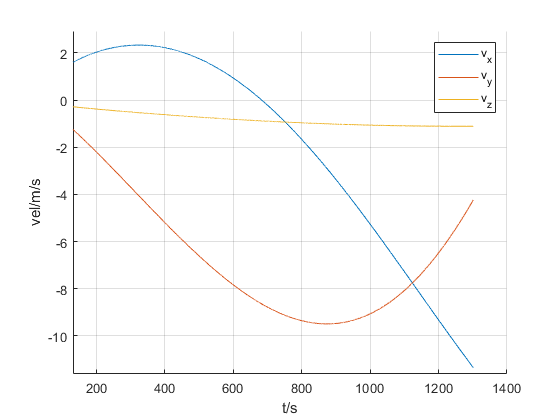

figure
hold on
plot(s(:, 1), s(:, 5 : 7))
grid on
legend('v_x', 'v_y', 'v_z')
xlabel('t/s')
ylabel('vel/m/s')
hold off

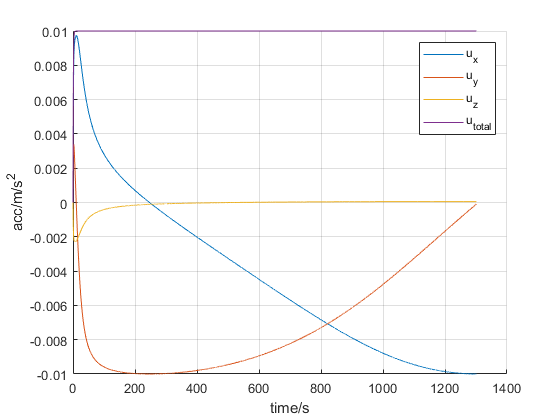

figure
hold on
plot(s(:, 1), s(:, 14 : 17))
grid on
legend('u_x', 'u_y', 'u_z', 'u_{total}')
xlabel('time/s')
ylabel('acc/m/s^2')
hold off